# Converter Bio Data

clc
clear all
close all

% biodata_file=".dataset/DATA 22-25/Measurement 25042024/Rifa_Back33.txt"
biodata_file=".dataset/DATA 22-25/Measurement 25042024/Rifa_Back4.txt"

biodata_file = ".dataset/DATA 22-25/Measurement 25042024/Rifa_Back4.txt"

dum_arr = split(biodata_file,"/");
new_name_arr = dum_arr(end-1) +"_"+dum_arr(end);
new_nam_str = replace(new_name_arr," ","_");
master_title = replace(new_nam_str,".","_");
master_save_path = ".dataset/"

master_save_path = ".dataset/"


table_raw = readtable(biodata_file);

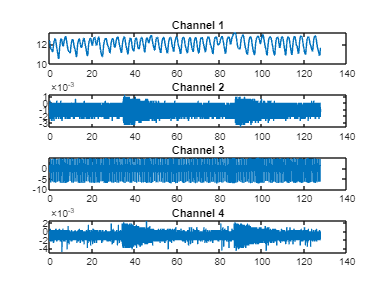

bio_freq = 2000;
bio_ts = 1/bio_freq;

table_data = table_raw(2:end,:);
table_size = size(table_data);

bio_t = bio_ts:bio_ts:(table_size*bio_ts);


bio_ch1   = table2array(table_data(:,1));
bio_ch2 = table2array(table_data(:,2));
bio_ch3 = table2array(table_data(:,3));
bio_ch4 = table2array(table_data(:,4));
% bio_ch4 = str2double(strrep(table2array(table_data(:,6)),",",'.'));


%% Visualize Raw Bio-data
figure("Name","Bio Signal Visualize")
% figure
subplot(4,1,1)
plot(bio_t,bio_ch1)
% xlim([10 20])
title('Channel 1');
subplot(4,1,2)
plot(bio_t,bio_ch2)
% xlim([10 20])
title('Channel 2');
subplot(4,1,3)
plot(bio_t,bio_ch3)
% xlim([10 20])
title('Channel 3');
subplot(4,1,4)
plot(bio_t,bio_ch4)
% xlim([10 20])
title('Channel 4');


savefig(master_save_path+"Figure_signal_"+master_title);

Get Spectrum All Data

% Compute power spectrum

% Generated by MATLAB(R) 23.2 and Signal Processing Toolbox 23.2.
% Generated on: 10-May-2024 13:42:26

% Parameters
timeLimits = [0.0005 127.519]; % seconds


%%
% Index into signal time region of interest
bio_ch1_ROI = bio_ch1(:);
timeValues = bio_t;
minIdx = timeValues >= timeLimits(1);
maxIdx = timeValues <= timeLimits(2);
bio_ch1_ROI = bio_ch1_ROI(minIdx&maxIdx);
timeValues = timeValues(minIdx&maxIdx);

% Parameters
Fs_bio_ch1 = bio_freq;
windowLength_bio_ch1 = 32768;
window_bio_ch1 = hamming(windowLength_bio_ch1,"periodic");
noverlap_bio_ch1 = 16384;
nfft_bio_ch1 = 32768;

% Compute spectral estimate
% Run the function call below without output arguments to plot the results
[Pbio_ch1_ROI,Fbio_ch1_ROI] = pwelch(bio_ch1_ROI,window_bio_ch1,noverlap_bio_ch1,nfft_bio_ch1,Fs_bio_ch1,...
    "power","onesided");

% Compute power spectrum

% Generated by MATLAB(R) 23.2 and Signal Processing Toolbox 23.2.
% Generated on: 10-May-2024 13:49:37

% Parameters
timeLimits = [0.0005 127.519]; % seconds


%%
% Index into signal time region of interest
bio_ch3_ROI = bio_ch3(:);
timeValues = bio_t;
minIdx = timeValues >= timeLimits(1);
maxIdx = timeValues <= timeLimits(2);
bio_ch3_ROI = bio_ch3_ROI(minIdx&maxIdx);
timeValues = timeValues(minIdx&maxIdx);

% Parameters
Fs_bio_ch3 = bio_freq;
windowLength_bio_ch3 = 56675;
window_bio_ch3 = hamming(windowLength_bio_ch3,"periodic");
noverlap_bio_ch3 = 28337;
nfft_bio_ch3 = 56675;

% Compute spectral estimate
% Run the function call below without output arguments to plot the results
[Pbio_ch3_ROI,Fbio_ch3_ROI] = pwelch(bio_ch3_ROI,window_bio_ch3,noverlap_bio_ch3,nfft_bio_ch3,Fs_bio_ch3,...
    "power","onesided");

bio_ch2_ROI = bio_ch2(:);
timeValues = bio_t;
minIdx = timeValues >= timeLimits(1);
maxIdx = timeValues <= timeLimits(2);
bio_ch2_ROI = bio_ch2_ROI(minIdx&maxIdx);
timeValues = timeValues(minIdx&maxIdx);

% Parameters
Fs_bio_ch2 = bio_freq;
windowLength_bio_ch2 = 56675;
window_bio_ch2 = hamming(windowLength_bio_ch2,"periodic");
noverlap_bio_ch2 = 28337;
nfft_bio_ch2 = 56675;

% Compute spectral estimate
% Run the function call below without output arguments to plot the results
[Pbio_ch2_ROI,Fbio_ch2_ROI] = pwelch(bio_ch2_ROI,window_bio_ch2,noverlap_bio_ch2,nfft_bio_ch2,Fs_bio_ch2,...
    "power","onesided");

bio_ch4_ROI = bio_ch4(:);
timeValues = bio_t;
minIdx = timeValues >= timeLimits(1);
maxIdx = timeValues <= timeLimits(2);
bio_ch4_ROI = bio_ch4_ROI(minIdx&maxIdx);
timeValues = timeValues(minIdx&maxIdx);

% Parameters
Fs_bio_ch4 = bio_freq;
windowLength_bio_ch4 = 56675;
window_bio_ch4 = hamming(windowLength_bio_ch4,"periodic");
noverlap_bio_ch4 = 28337;
nfft_bio_ch4 = 56675;

% Compute spectral estimate
% Run the function call below without output arguments to plot the results
[Pbio_ch4_ROI,Fbio_ch4_ROI] = pwelch(bio_ch4_ROI,window_bio_ch4,noverlap_bio_ch4,nfft_bio_ch4,Fs_bio_ch4,...
    "power","onesided");



% figure
figure("Name","Bio Signal Spectrum Visualize")
subplot(4,1,1)
plot(Fbio_ch1_ROI,Pbio_ch1_ROI)
title("Spectrum Ch1")
xlabel("Frequency(Hz)")
xlim([0 10])
subplot(4,1,2)
plot(Fbio_ch2_ROI,Pbio_ch2_ROI)
title("Spectrum Ch2")
xlabel("Frequency(Hz)")
xlim([0 10])
subplot(4,1,3)
plot(Fbio_ch3_ROI,Pbio_ch3_ROI)
title("Spectrum Ch3")
xlabel("Frequency(Hz)")
xlim([0 10])
subplot(4,1,4)
plot(Fbio_ch4_ROI,Pbio_ch4_ROI)
title("Spectrum Ch4")
xlabel("Frequency(Hz)")
xlim([0 10])

savefig(master_save_path+"Figure_signal_spectrum_"+master_title);